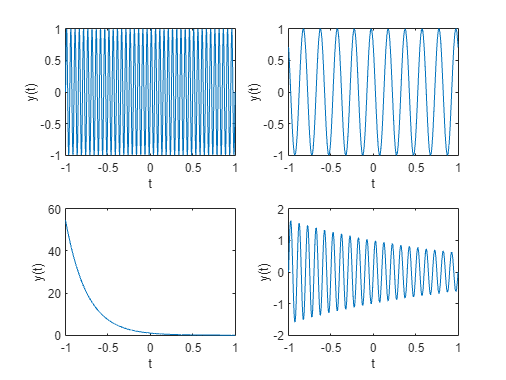

%Q1
a=1+mod(256,3);
t=-1:0.001:1;
y1=sin(20*pi*a*t);
subplot(2,2,1)
plot(t,y1)
y2=cos(5*pi*a*t+(pi/4));
subplot(2,2,2)
plot(t,y2)
y3=exp(-2*a*t);
subplot(2,2,3)
plot(t,y3)
y4=exp(-0.25*a*t).*(sin(20*pi*t));
subplot(2,2,4)
plot(t,y4)

subplot(2,2,1)
xlabel("t")

subplot(2,2,2)
ylabel("y(t)")
subplot(2,2,4)

subplot(2,2,1)

subplot(2,2,2)
xlabel("t")

subplot(2,2,1)
ylabel("y(t)")

subplot(2,2,3)
xlim([-1.00 1.00])
ylim([0 60])
xlabel("t")
ylabel("y(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y(t)")

%Q2
a=1+mod(256,3);
t=-5:0.001:5;
x=exp(-a*t)

x = 1.0e+04 *

    2.2026    2.1982    2.1939    2.1895    2.1851    2.1807    2.1764    2.1720    2.1677    2.1634    2.1590    2.1547    2.1504    2.1461    2.1418    2.1375    2.1333    2.1290    2.1248    2.1205    2.1163    2.1121    2.1078    2.1036    2.0994    2.0952    2.0910    2.0869    2.0827    2.0785    2.0744    2.0702    2.0661    2.0620    2.0578    2.0537    2.0496    2.0455    2.0414    2.0374    2.0333    2.0292    2.0252    2.0211    2.0171    2.0131    2.0090    2.0050    2.0010    1.9970


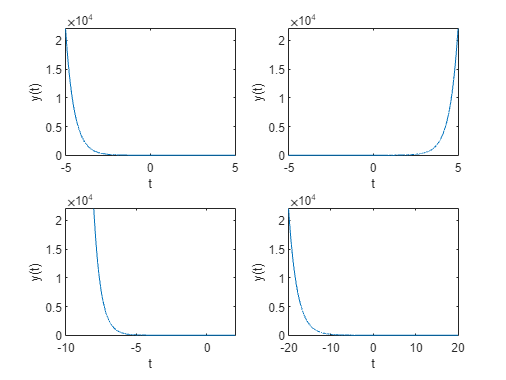

subplot(2,2,1)
plot(t,x)
subplot(2,2,2)
plot(-t,x)
subplot(2,2,3)
plot(t-(1.5*a),x)
subplot(2,2,4)
plot(2*a*t,x)

subplot(2,2,1)
xlabel("t")
ylabel("y(t)")
subplot(2,2,2)
xlabel("t")
ylabel("y(t)")
subplot(2,2,3)
xlabel("t")
ylabel("y(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y(t)")

%Q3
ecg=load("ECG_Data.txt")

ecg =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


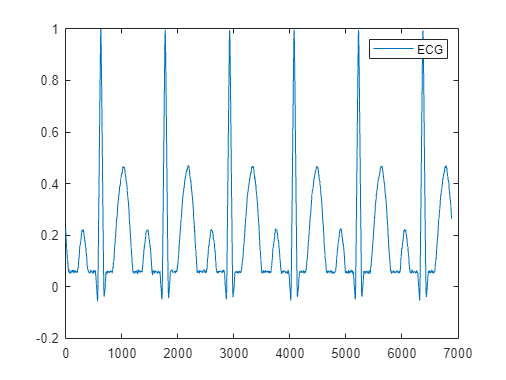

subplot(1,1,1)
plot(ecg)
% 'C:\Users\SNEHA SRI\Documents\MATLAB\New Folder\Experiment-1\Experiment-1'
legend("ECG")

jan_rain=load("RainFallIndia_Jan.txt")

jan_rain =   107.3000
   43.7000
   32.7000
   42.2000
   33.3000
   28.0000
   42.2000
   42.2000
   83.7000
   70.3000


nbins=5

nbins = 5

histogram(jan_rain,nbins)
hold on
july_rain=load("RainFallIndia_July.txt")

july_rain = 1.0e+03 *

    0.2850
    0.4213
    0.4654
    0.6601
    0.9909
    0.2174
    0.8519
    0.6601
    0.2720
    0.4608


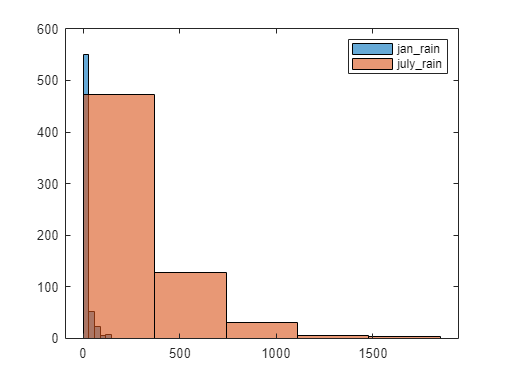

histogram(july_rain,nbins)
hold off

legend("show")

m=[jan_rain;july_rain]

m = 1.0e+03 *

    0.1073
    0.0437
    0.0327
    0.0422
    0.0333
    0.0280
    0.0422
    0.0422
    0.0837
    0.0703


mean(m)

ans = 172.2224

std(m)

ans = 220.0828

[y,Fs]=audioread('Track002.wav')

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 48000

sound(y,Fs)

%Q5
t=[0:0.001:5];
a=sin(200*t);
b=sin(220*t);
c=[a,b];

filename='convaluted_signal.wav';
audiowrite(filename,c,44100)
[y Fs]=audioread("convaluted_signal.wav");
sound(y,Fs)






%Q5
notes=["Do" "Re" "Mi" "Fa" "So" "La" "Ti" "Do"];
freq=[261.6 293.6 329.6 349.2 392.0 440.0 493.8 523.25];

a=[];
for n=1:8
   t=0:0.000125:1; % Note duration
  a=[a sin(2*pi*freq(n)*t)]; % Signal
end
sound(a);

% Saving as .wav file
Fs=44100;
filename="DoReMi.wav";
audiowrite(filename,a,Fs);

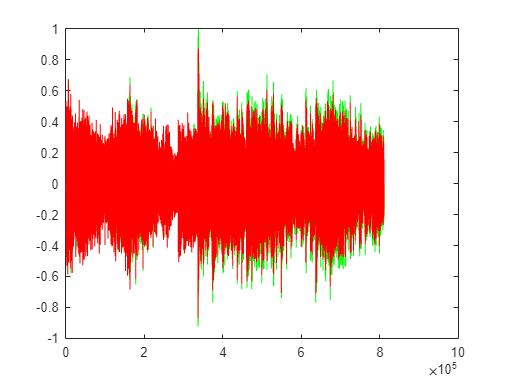

%Q7
a=audioread('Track002.wav');
b=load('ConvFile1.txt');
c=conv(a,b);
max_amplitude=max(max(c),abs(min(c)));
c=c/max_amplitude;
filename='convaluted_signal1.wav';
audiowrite(filename,c,44100)
[y Fs]=audioread("convaluted_signal1.wav");
sound(y,Fs)
t=0:length(a)-1;
%subplot(2,1,1)
%plot(t,a)
t1=0:length(c)-1;
subplot(1,1,1)
plot(t1,c,'g',t,a,'r')

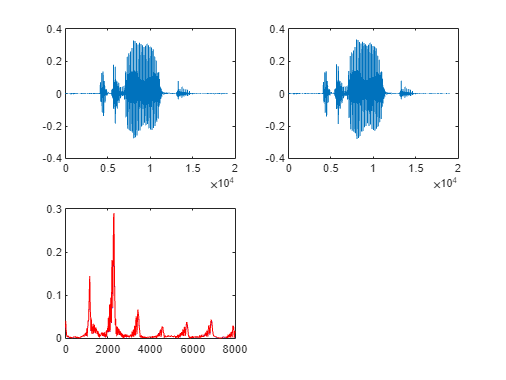

%Q4
a=1+mod(256,3);
f=250*a;
data=importdata("speech.wav");
[s,Fs]=audioread("speech.wav");
y1=fn(s,f,Fs);
t=1/Fs; L=1500; t=(0:L-1)*t;
y0=fft(y1);
s0=fft(s);
f=Fs*(0:(L/2))/L;
P2=abs(y0/L);
P1=P2(1:L/2+1);
P1(2:end-1)=2*P1(2:end-1);
Q2=abs(s0/L);
Q1=Q2(1:L/2+1);
Q1(2:end-1)=2*Q1(2:end-1);
subplot(2,2,1);
plot(y1);
subplot(2,2,2);
plot(s);
subplot(2,2,3);
plot(f,P1,'blue',f,Q1,'red');



sound(y,Fs)


function y=fn(s,F,Fs)
y=s.*cos(2.*pi.*F./Fs);
end






